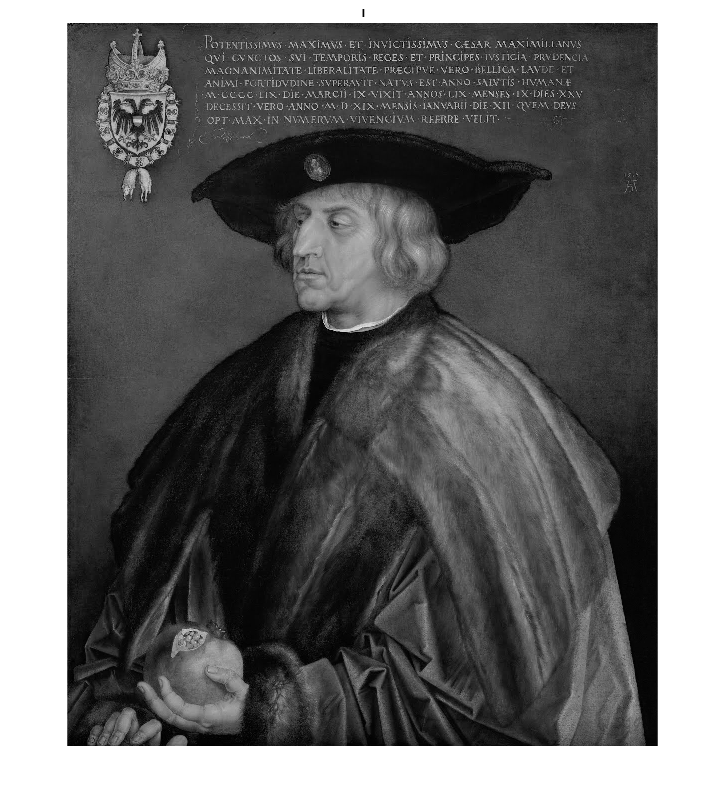

% Convert RGB image to CIElab

% load RGB image

src = 'Fabric.jpg';
rgb = imread(src);


% Convert to lab

labTransformation = makecform('srgb2lab');
lab = applycform(rgb,labTransformation);

% Separate l,a,b

l = lab(:,:,1);
a = lab(:,:,2);
b = lab(:,:,3);

figure, imshow(l), title('l');

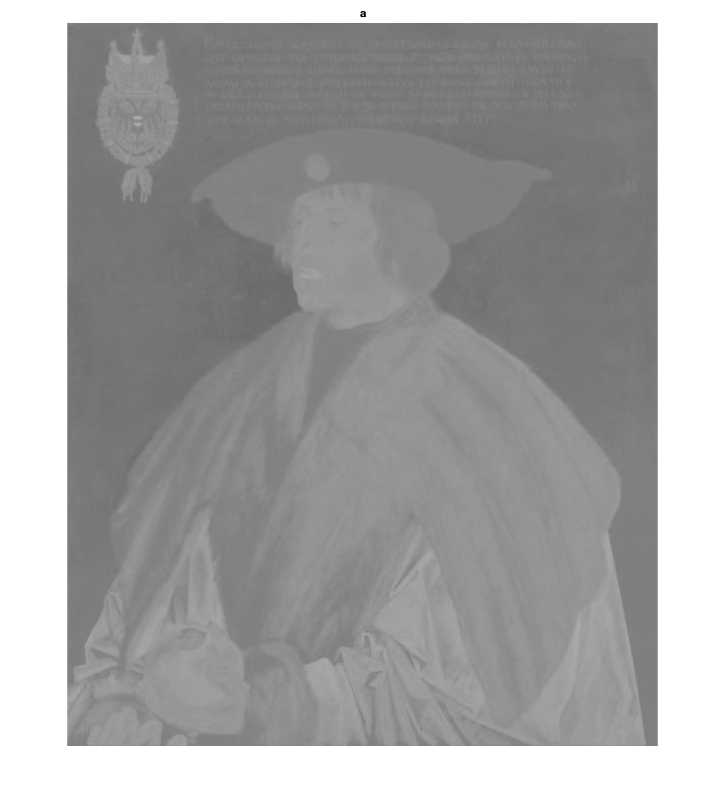

figure, imshow(a), title('a');

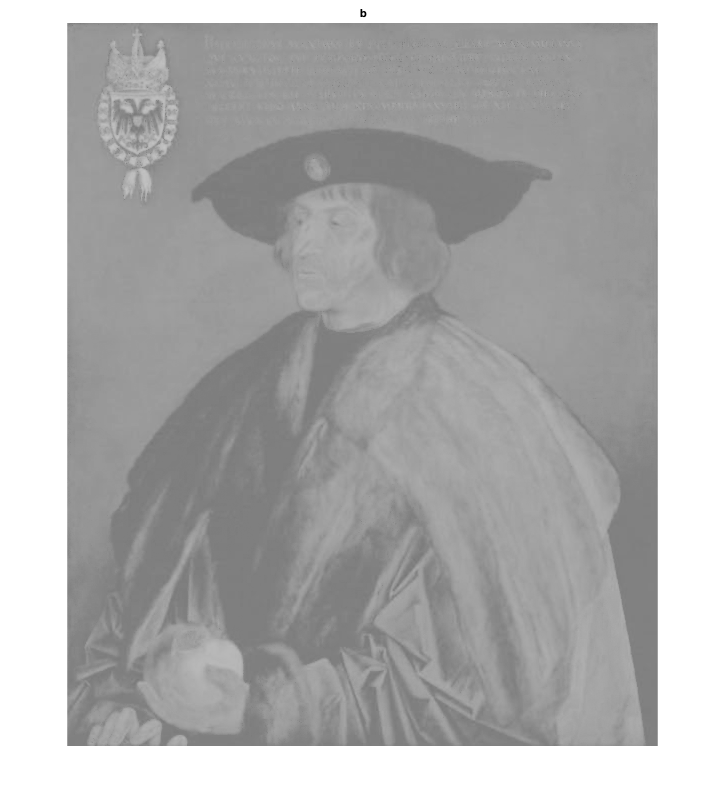

figure, imshow(b), title('b');

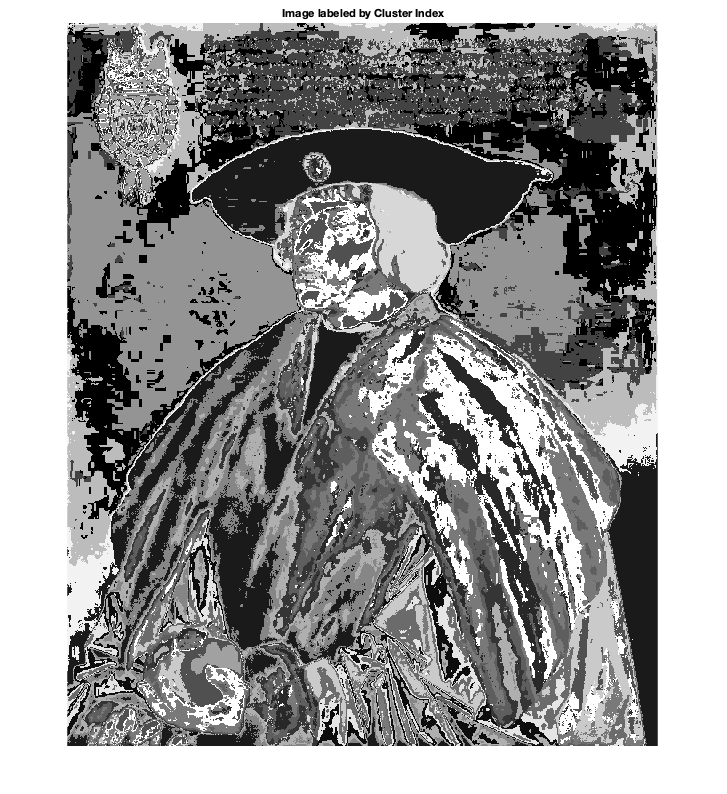


% Classify the colors in a*b* space using K-means Clustering

ab = lab(:,:,2:3);
ab = im2single(ab);
nColors = 20;

% repeat the clustering 3 times to avoid local minima

pixel_labels = imsegkmeans(ab,nColors,'NumAttempts',3);
imshow(pixel_labels,[]);
title('Image labeled by Cluster Index');

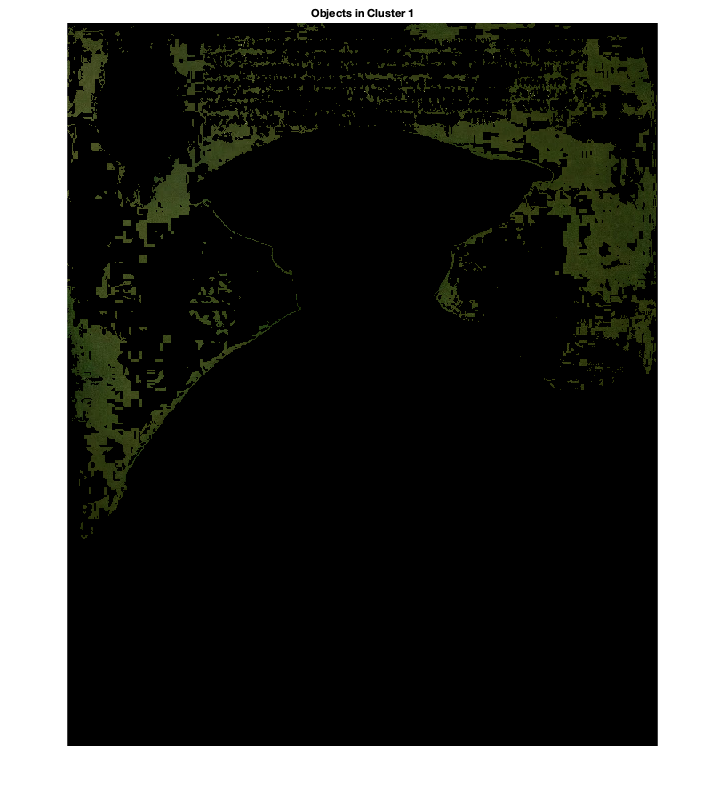


mask1 = pixel_labels==1;
cluster1 = rgb .* uint8(mask1);
imshow(cluster1)
title('Objects in Cluster 1');

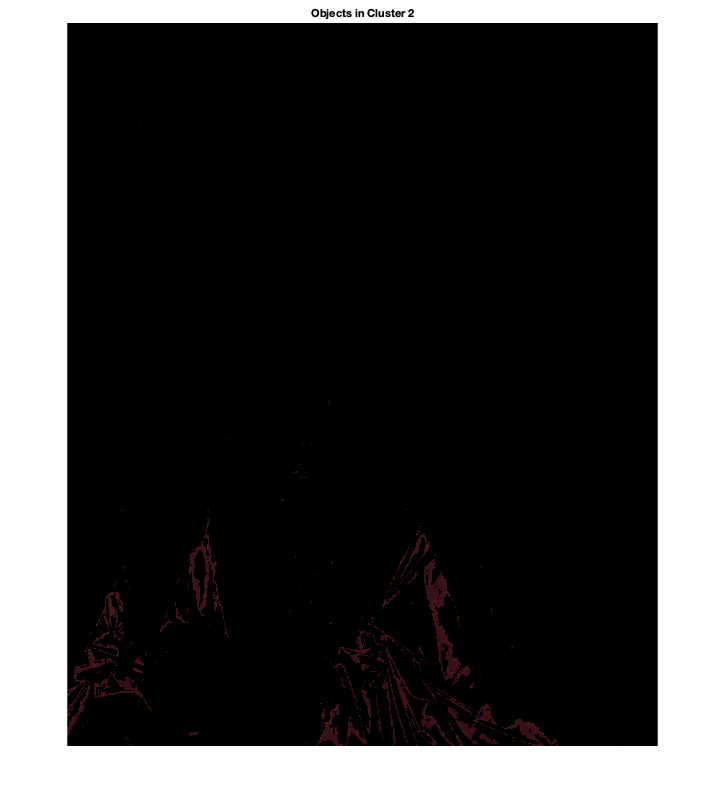


mask2 = pixel_labels==2;
cluster2 = rgb .* uint8(mask2);
imshow(cluster2)
title('Objects in Cluster 2');

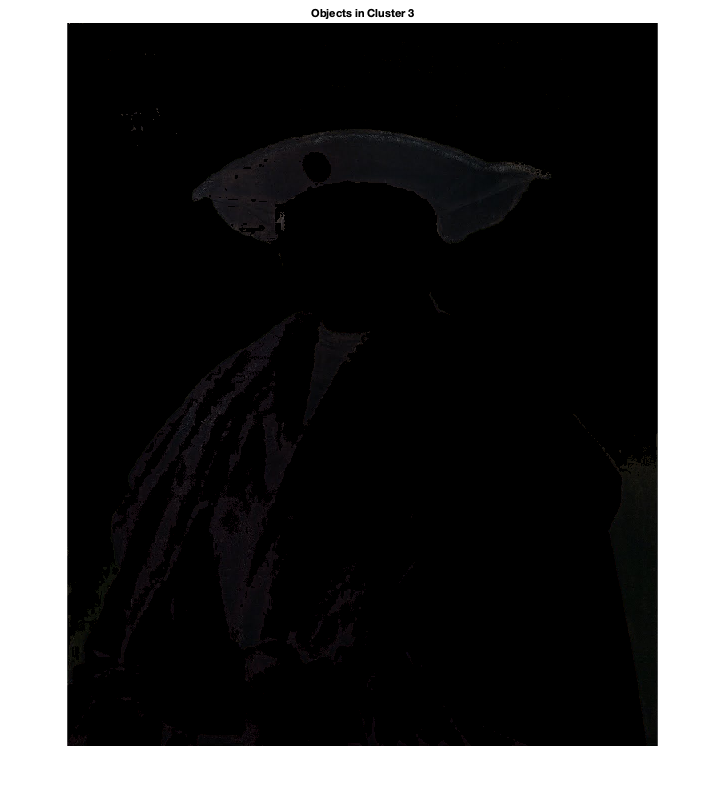


mask3 = pixel_labels==3;
cluster3 = rgb .* uint8(mask3);
imshow(cluster3)
title('Objects in Cluster 3');


% Convert cIElab image to LCh image